## Steady State Fan Data

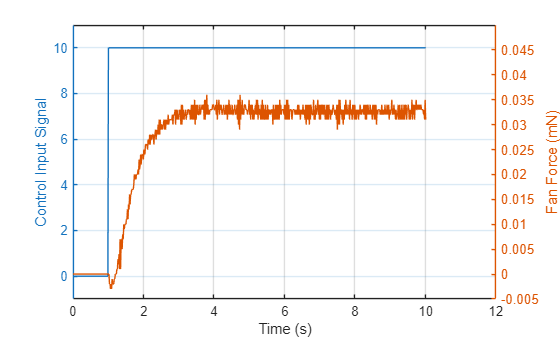

% data_ss = readmatrix('Steady State Measurements.xlsx');
% V_ab = data_ss(:, 1);          % Fan voltage input (V)
% Fss_ab = data_ss(:, 2);          % Steady-state fan thrust output (N)
% [beta, alpha] = voltage2FanCoeffs(data_ss)
% 
% plot(V_ab,Fss_ab,'bx');           % plot raw thrust data
% grid on; hold on;
% xlabel('Fan Voltage (V)');
% ylabel('Output Thrust (N)');
% plot(V_ab,alpha*V_ab+beta,'-'); % plot linear approximation

FanDynData = load('FanDynData.txt');

startOffset = 1;
endOffset = 50;

tt = FanDynData(1,startOffset:end)';
u = FanDynData(2,startOffset:end)';
y_raw = FanDynData(3,startOffset:end)';
y_median = medfilt1(y_raw, 100);
y_median_smoothed = movmean(y_median, 30);

figure(1)
yyaxis left
plot(tt,u)
ylabel('Control Input Signal')
ylim([-1, 11])

yyaxis right
plot(tt,y_raw)
ylabel('Fan Force (mN)')
ylim([-0.005, 0.05])

grid on
xlabel('Time (s)')

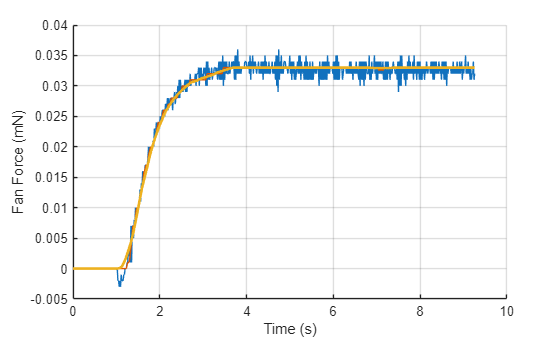


figure(2)
grid on
hold on
plot(tt(1:end-endOffset, :), y_raw(1:end-endOffset, :));
plot(tt(1:end-endOffset, :), y_median(1:end-endOffset, :))
plot(tt(1:end-endOffset, :), y_median_smoothed(1:end-endOffset, :), 'LineWidth', 2)
ylabel('Fan Force (mN)')
xlabel('Time (s)')

%% System Identification
Ts_fan = 0.015; % Sampling period of fan sysid DAQ

% Use smoothed output for modelling
data = iddata(y_median_smoothed(1:end-endOffset), u(1:end-endOffset), Ts_fan);

fanModelOrder = 2;  % model order
sys_fan = n4sid(data, fanModelOrder, 'Ts', 0, ...
    'Form', 'canonical');

sys_fan;
k_fan = dcgain(sys_fan)

k_fan = 0.0033

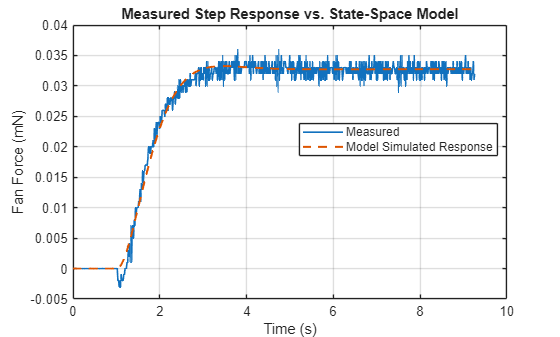

% bode(sys_fan)

A_fan = sys_fan.A;
B_fan = sys_fan.B;

% stepConfig = RespConfig;
% stepConfig.InitialState = [F_e_real; 0];
% % stepConfig.Amplitude = FanSteadyStateLUT(F_e_real);
% stepConfig.Amplitude = 4.6;
% 
% figure(3);
% step(sys_fan, stepConfig)

[y_sim, ~, x_sim] = sim(sys_fan, data); % Simulate response

figure(4); clf;
plot(tt(1:end-endOffset), y_raw(1:end-endOffset), 'LineWidth', 1.2);
hold on;
plot(tt(1:end-endOffset), y_sim.OutputData, '--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Fan Force (mN)');
title('Measured Step Response vs. State-Space Model');
legend('Measured', 'Model Simulated Response', 'Location', 'Best');
grid on;

## Duplicate Model and Combine

Model with alternated states:

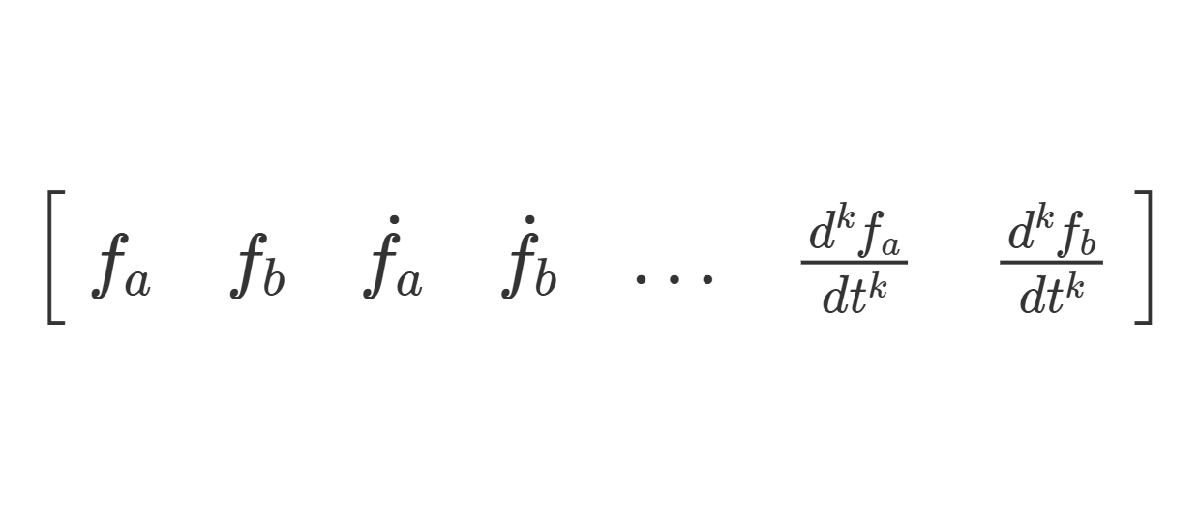

A_fans = kron(sys_fan.A, eye(2))

A_fans =          0         0    1.0000         0
         0         0         0    1.0000
   -4.4582         0   -3.3631         0
         0   -4.4582         0   -3.3631


B_fans = kron(sys_fan.B, eye(2))

B_fans =    -0.0001         0
         0   -0.0001
    0.0149         0
         0    0.0149


C_fans = kron(sys_fan.C, eye(2));
D_fans = kron(sys_fan.D, eye(2));

sys_fans = ss(A_fans, B_fans, C_fans, D_fans);

## Symbolic Representation

syms F_dot_a(t) F_dot_b(t) F_ddot_a(t) F_ddot_b(t)
syms U_a U_b

% Create symbolic variables for the fan states based on order
X_fans = [F_a; F_b];
U_fans = [U_a; U_b]

$$U\_fans = \left(\begin{array}{c} U_{a}\\ U_{b} \end{array}\right)$$

F_dots = [F_dot_a; F_dot_b; F_ddot_a; F_ddot_b];
F_dots = formula(F_dots);

for c = 1:fanModelOrder-1
    X_fans = [X_fans; diff(F_a, t, c); diff(F_b, t, c)];
    X_fans = subs(X_fans, diff(F_a, t, c), F_dots(2*c-1));
    X_fans = subs(X_fans, diff(F_b, t, c), F_dots(2*c));
end

X_fans

$$X\_fans(t) = \left(\begin{array}{c} F_{a}\left(t\right)\\ F_{b}\left(t\right)\\ {\dot{F}}_{a}\left(t\right)\\ {\dot{F}}_{b}\left(t\right) \end{array}\right)$$

f_fans = A_fans*X_fans + B_fans*U_fans

$$f\_fans(t) = \left(\begin{array}{c} {\dot{F}}_{a}\left(t\right)-\frac{906020227046945\,U_{a}}{9223372036854775808}\\ {\dot{F}}_{b}\left(t\right)-\frac{906020227046945\,U_{b}}{9223372036854775808}\\ \frac{537534613439163\,U_{a}}{36028797018963968}-\frac{1254872290558159\,F_{a}\left(t\right)}{281474976710656}-\frac{7572997055808805\,{\dot{F}}_{a}\left(t\right)}{2251799813685248}\\ \frac{537534613439163\,U_{b}}{36028797018963968}-\frac{1254872290558159\,F_{b}\left(t\right)}{281474976710656}-\frac{7572997055808805\,{\dot{F}}_{b}\left(t\right)}{2251799813685248} \end{array}\right)$$